clear
%read all images, normalize and create eigenfaces
commonsize = [300,300];
[DataMatrix, ImageFiles] = normalize_all_images("../db/DB1/", commonsize);
[meanface, eigenVectors, weights] = compute_eigenfaces(DataMatrix,commonsize);

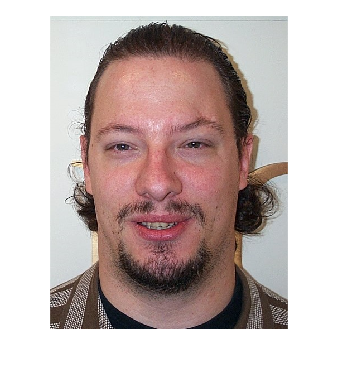

img = imread("..\db\DB1\db1_05.jpg"); %5 , 8 
imshow(img);

id = isPersonInSet(img, meanface, eigenVectors, commonsize);

if id < 1
    error = 404
elseif id < 10
    identified_img = imread("..\db\DB1\db1_0" + id +".jpg");
    imshow(identified_img)
else
    identified_img = imread("..\db\DB1\db1_" + id +".jpg");
    imshow(identified_img)
end

id

id = 5

% id = tnm034(img)